clc,clear, close all

dataFolder = 'C:\Users\raffb\ECE465_Project\Dataset\Dataset';

%imds = imageDatastore(dataFolder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames')
imds = imageDatastore(dataFolder, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

img = readimage(imds, 1);
imgSize = size(img)

imgSize =    480   640


% Original Dataset directory and output one for the resized images 
baseDir = 'C:\Users\raffb\ECE465_Project\Dataset\Dataset'; 
outputDir = 'C:\Users\raffb\ECE465_Project\Dataset\ResizeAll'; 
targetSize = [480 640]; % Size to resize images to (dimensions of first image in the 1st folder)


imds = imageDatastore(baseDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
labels = categories(imds.Labels);

% Creates subfolder structure in the output directory for the classes of
% the original dataset folder

for i = 1:length(labels)
    currDir = fullfile(outputDir, char(labels(i)));
    if ~exist(currDir, 'dir'), mkdir(currDir); end
end

% For the length of the dataset folders, iterates through the images 
for i = 1:length(imds.Files)
    img = readimage(imds, i);

    % Resize while maintaining aspect ratio
    [h, w] = size(img);
    scale = min(targetSize(1)/h, targetSize(2)/w);
    newSize = round([h w] * scale);
    imgResized = imresize(img, newSize);

    % Center-pad with zeros to reach target dimensions
    padImg = zeros(targetSize, 'like', img);
    rOff = floor((targetSize(1) - newSize(1))/2) + 1;
    cOff = floor((targetSize(2) - newSize(2))/2) + 1;
    padImg(rOff:rOff+newSize(1)-1, cOff:cOff+newSize(2)-1) = imgResized;

    % Save to the new subfolder
    [~, name, ext] = fileparts(imds.Files{i});
    savePath = fullfile(outputDir, char(imds.Labels(i)), [name, ext]);
    imwrite(padImg, savePath);
end


newImds = imageDatastore(outputDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
[imdsTrain, imdsVal] = splitEachLabel(newImds, 0.8, 'randomized');

numClasses = numel(categories(newImds.Labels));


% Define source and destination root folders
sourceRoot = 'C:\Users\raffb\ECE465_Project\Dataset\ResizeAll';
destRoot = 'C:\Users\raffb\ECE465_Project\Dataset\Resized_less';

% Get list of all items in source folder
items = dir(sourceRoot);
% Filter to get only subfolders, excluding '.' and '..'
subfolders = items([items.isdir] & ~ismember({items.name}, {'.', '..'}));

for i = 1:length(subfolders)
    folderName = subfolders(i).name;
    currentSourceDir = fullfile(sourceRoot, folderName);
    currentDestDir = fullfile(destRoot, folderName);
    
    % Create the corresponding subfolder in the destination if it doesn't exist
    if ~exist(currentDestDir, 'dir')
        mkdir(currentDestDir);
    end
    
    % Get list of image files (adjust extensions as needed)
    imageFiles = [dir(fullfile(currentSourceDir, '*.jpg')); ...
                  dir(fullfile(currentSourceDir, '*.png')); ...
                  dir(fullfile(currentSourceDir, '*.tif'))];
    
    % Limit to the first # images
    numToCopy = min(200, length(imageFiles));
    
    for j = 1:numToCopy
        sourceFile = fullfile(currentSourceDir, imageFiles(j).name);
        destFile = fullfile(currentDestDir, imageFiles(j).name);
        
        % Copy the file
        copyfile(sourceFile, destFile);
    end
    fprintf('Copied %d images from %s\n', numToCopy, folderName);
end

Copied 200 images from F0
Copied 200 images from F1
Copied 200 images from F2
Copied 200 images from F3
Copied 200 images from F4


resizedDataFolder = 'C:\Users\raffb\ECE465_Project\Dataset\Resized_less';



%imds_new = imageDatastore(resizedDataFolder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames')

imds_new = imageDatastore(resizedDataFolder, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');
 

% Split into 70% training and 30% validation
[imdsTrain_new, imdsValidation_new] = splitEachLabel(imds_new, 0.7, 'randomized');




layers = [
  
    imageInputLayer([480, 640, 1])

    convolution2dLayer(3, 8, 'Padding', 'same');
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2);

    convolution2dLayer(3, 16, 'Padding', 'same');
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2);

    convolution2dLayer(3,32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer


    convolution2dLayer(3,64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    fullyConnectedLayer(5)
    softmaxLayer
    classificationLayer];






% Training Options
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 32, ...
    'Plots', 'training-progress');



Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:08 |        0.00% |       2.1548 |          0.0010 |
|       3 |          50 |       00:04:08 |       62.50% |      21.7809 |          0.0010 |
|       5 |         100 |       00:08:07 |      100.00% |   3.7253e-09 |          0.0010 |
|       8 |         150 |       00:12:07 |       96.88% |       0.1584 |          0.0010 |
|      10 |         200 |       00:17:57 |      100.00% |   0.0000e+00 |          0.0010 |
|      12 |         250 |       00:38:21 |      100.00% |   0.0000e+00 |          0.0010 |
|      15 |         300 |  

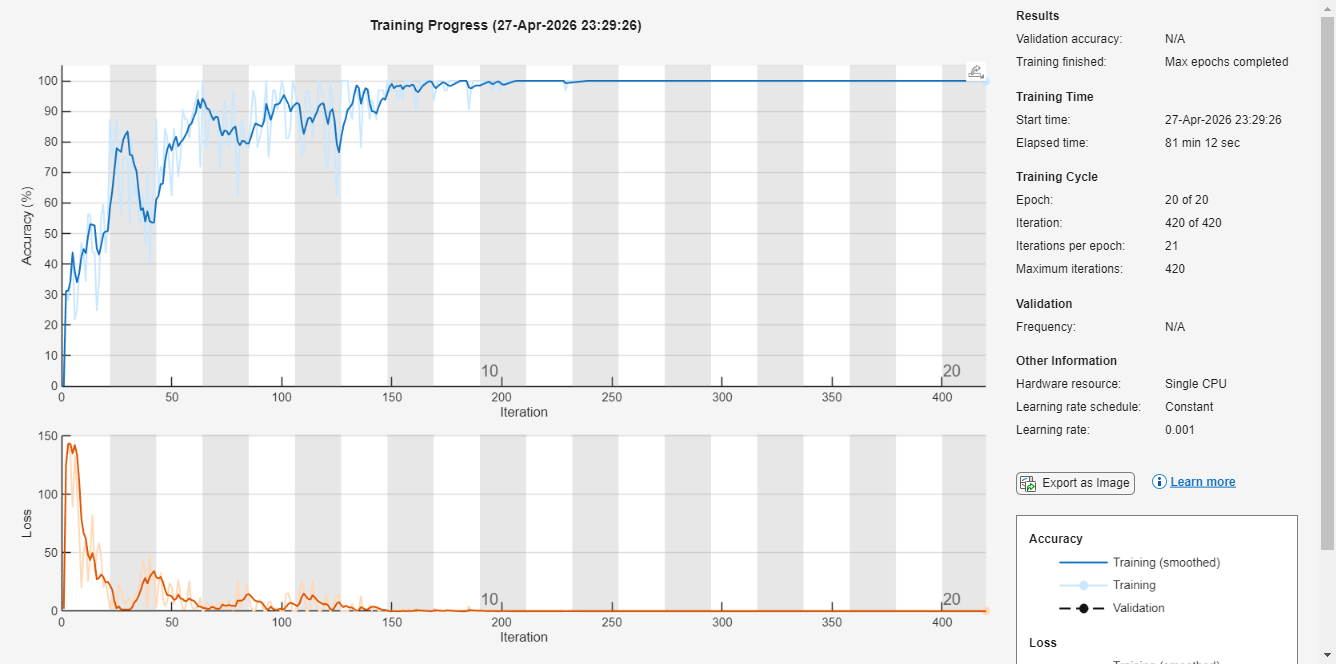

% Train the convolutional neural network
net = trainNetwork(imdsTrain_new, layers, options);

% Evaluate the network on the validation set
predictedLabels = classify(net, imdsValidation_new);
actualLabels = imdsValidation_new.Labels;
acc = sum(predictedLabels == actualLabels)/numel(actualLabels)

acc = 0.7133

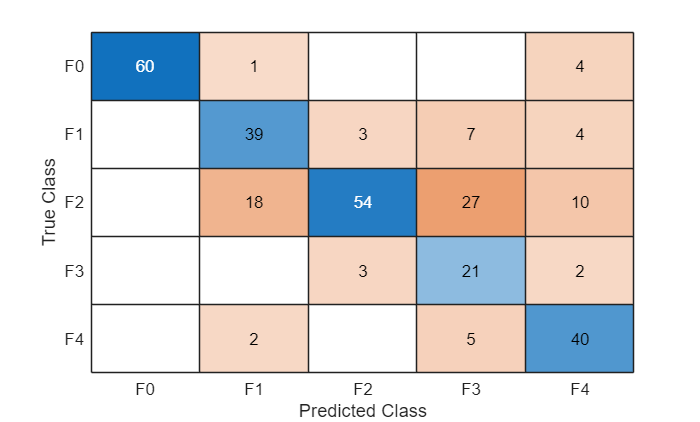

confusionchart(predictedLabels, actualLabels)

% Assuming 'net' is your trained network variable
save('trainedLiverImageClassifier.mat', 'net'); 



% Load the model back into the workspace
testData = load('trainedLiverImageClassifier.mat'); 



% Now you can use 'net' to make predictions on new data
%YPredicted = predict(net, newData); 


trainedNet = testData.net;

% Define source and destination root directories
sourceRoot = 'C:\Users\raffb\ECE465_Project\Dataset\ResizeAll';
destRoot = 'C:\Users\raffb\ECE465_Project\Dataset\Resized_less_test';

% Get list of all subfolders (excluding current and parent directories)
allDirs = dir(sourceRoot);
subFolders = allDirs([allDirs.isdir]);
subFolders = subFolders(~ismember({subFolders.name}, {'.', '..'}));

for k = 1:length(subFolders)
    % Define paths for current subfolder and its corresponding destination
    currentSubName = subFolders(k).name;
    currentSourceDir = fullfile(sourceRoot, currentSubName);
    currentDestDir = fullfile(destRoot, currentSubName);
    
    % Create the subfolder in the destination if it doesn't exist
    if ~exist(currentDestDir, 'dir')
        mkdir(currentDestDir);
    end


    % Get all images (e.g., .jpg, .png) in the current subfolder
    imgFiles = dir(fullfile(currentSourceDir, '*.jpg')); % Adjust extension as needed
    
    % Copy files in the specified range (100 to 200)
    % numel checks if there are enough files to avoid indexing errors
    endIdx = min(600, numel(imgFiles));
    if numel(imgFiles) >= 400
        for i = 100:endIdx
            sourceFile = fullfile(currentSourceDir, imgFiles(i).name);
            copyfile(sourceFile, currentDestDir);
        end
    end
end




resizedDataFolder_test = 'C:\Users\raffb\ECE465_Project\Dataset\Resized_less_test';


imds_new = imageDatastore(resizedDataFolder_test, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

[imdsTrain_test, imdsVal_test] = splitEachLabel(imds_new, 0.8, 'randomized');

YPredicted = classify(trainedNet, imdsVal_test); 



actualLabels = imdsVal_test.Labels;
acc = sum(YPredicted == actualLabels)/numel(actualLabels)

acc = 0.7700

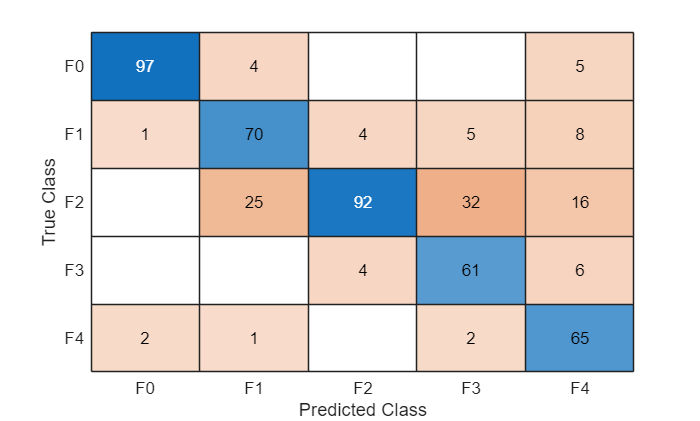

confusionchart(YPredicted, actualLabels)